# **Problem E11.25**

In this problem we are tasked with implementing the backpropagation algorithm for a $1-S^1 -1$ network in order to perform function approximation. To that end, we will a network with sigmoid activation on the hidden layer and a linear activation on the output layer.

Because we are asked to repeat the experiment several times, we have implemented the algorithm as a function in "MLP.mlx" that takes $X$ and $Y$, the inputs and targets, $S^1$, the number of hidden neurons along with $\eta$, learning rate of the algorithm. The implementation of the backprop algorithm is fully explained in "MLP.mlx".

We will first generate a set of inputs and outputs for our problem which is approximating the function below:


$$g\left(p\right)=1+\sin \left(\frac{\pi }{2}p\right),\textrm{for}-2\le p\le 2$$


We will also generate a test set that the network never sees and use this to evaluate how well the model interpolates.

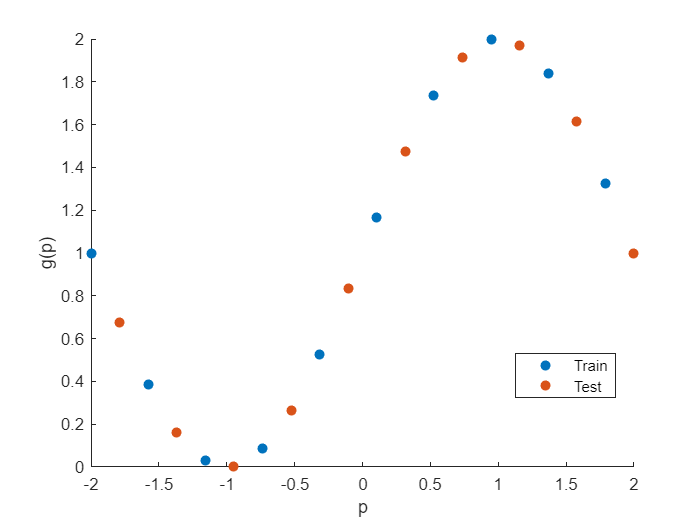

X = linspace(-2, 2, 20); % 20 linearly spaced vectors between -2 and 2
Y = 1 + sin(X.*pi/2);
% keep odd indices for training and even indices for testing
X_train = X(1:2:end);
Y_train = Y(1:2:end);
X_test = X(2:2:end);
Y_test = Y(2:2:end);
scatter(X, Y, 'filled');
hold on;
scatter(X_test, Y_test, 'filled');
legend('Train', 'Test', 'Location','best');
xlabel('p');
ylabel('g(p)');
hold off;

We can now begin with the experiments. For each $S^1 =2\;$and $S^1 =10$ we will test two values of $\eta \;$namely $0\ldotp 1$ and $1$ to see the changes in convergence. And finally, in order to show overfitting we will test a network with $S^1 =100$ and $\eta =0\ldotp 02$.

% Experiment 1: Hidden = 2, Eta = 0.1
[W1, W2, b1, b2, cost_hist] = MLP(X_train,Y_train,2,0.1);

Loss at the end of epoch 100: 0.088880
Loss at the end of epoch 200: 0.071011
Loss at the end of epoch 300: 0.060341
Loss at the end of epoch 400: 0.054072
Loss at the end of epoch 500: 0.050079
Loss at the end of epoch 600: 0.047555
Loss at the end of epoch 700: 0.046019
Loss at the end of epoch 800: 0.045119
Loss at the end of epoch 900: 0.044615
Loss at the end of epoch 1000: 0.044354


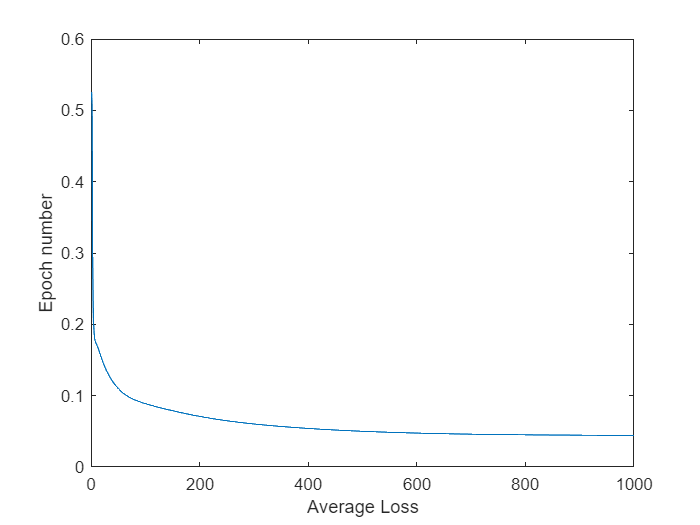

plot(cost_hist);
xlabel('Average Loss')
ylabel('Epoch number')

As we can see from the cost history, the cost value has decreased in every iteration until it converges to around 0.025 and changes minimally after that. In order to see how the network has performed we will present the inputs to network once again and plot the network response against expected responses.

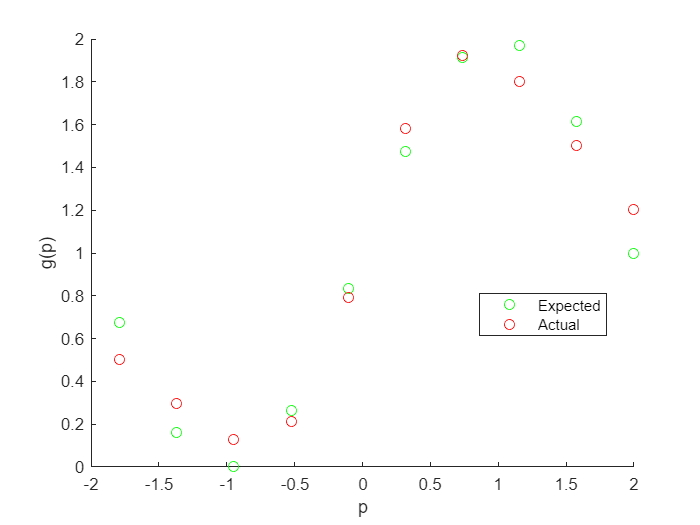

Y_pred = purelin(W2*logsig(W1*X_test + b1) + b2);
scatter(X_test, Y_test, 'green');
hold on;
scatter(X_test, Y_pred, 'red');
xlabel('p');
ylabel('g(p)');
legend('Expected', 'Actual', 'Location','best');
hold off;

As we can see the network has produced a decent fit on the test inputs although it is still erroneous at some points. Especially near values of $p$ close to $2$.

% Experiment 2: Hidden = 2, Eta = 1
[W1, W2, b1, b2, cost_hist] = MLP(X_train,Y_train,2,1);

Loss at the end of epoch 100: 1839.639568
Loss at the end of epoch 200: 5978.929570
Loss at the end of epoch 300: 12480.801180
Loss at the end of epoch 400: 21329.867711
Loss at the end of epoch 500: 32536.038000
Loss at the end of epoch 600: 46099.312044
Loss at the end of epoch 700: 62019.689845
Loss at the end of epoch 800: 80297.171401
Loss at the end of epoch 900: 100931.756711
Loss at the end of epoch 1000: 123923.445775


As we can see, with a poor choice of learning rate, not only does the cost function decrease, it increases without bounds and goes to infinity only after about 180 epochs.

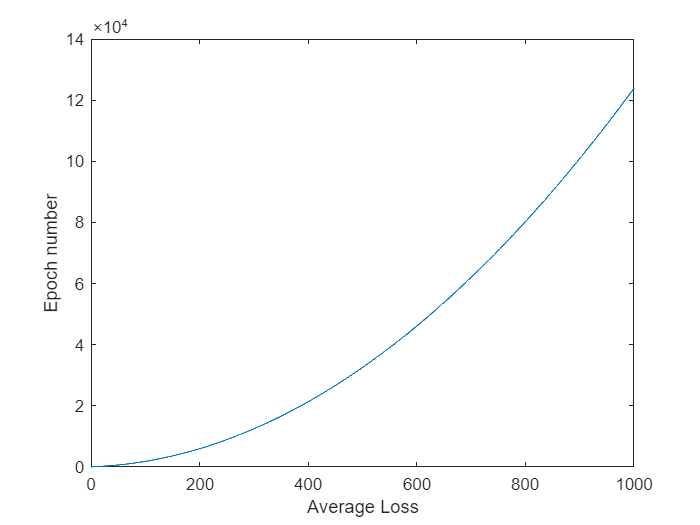

plot(cost_hist);
xlabel('Average Loss')
ylabel('Epoch number')

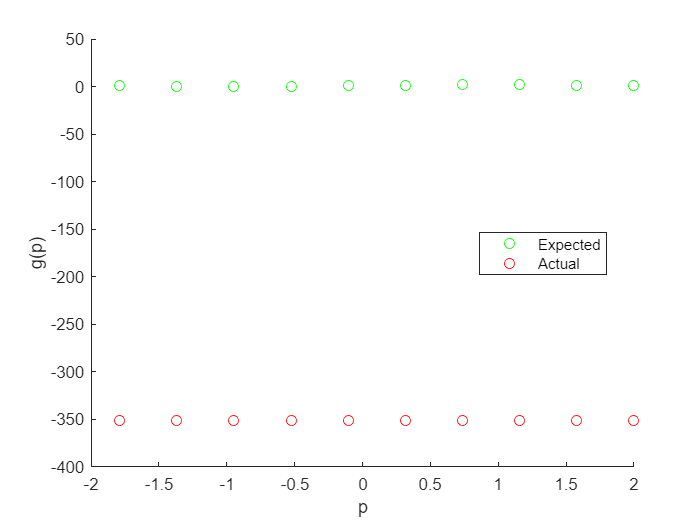

Y_pred = purelin(W2*logsig(W1*X_test + b1) + b2);
scatter(X_test, Y_test, 'green');
hold on;
scatter(X_test, Y_pred, 'red');
xlabel('p');
ylabel('g(p)');
legend('Expected', 'Actual', 'Location','best');
hold off;

The produced outputs are extremly off from actual values as well.

% Experiment 3: Hidden = 10, Eta = 0.1
[W1, W2, b1, b2, cost_hist] = MLP(X,Y,10,0.1);

Loss at the end of epoch 100: 0.025286
Loss at the end of epoch 200: 0.019891
Loss at the end of epoch 300: 0.013299
Loss at the end of epoch 400: 0.008081
Loss at the end of epoch 500: 0.004440
Loss at the end of epoch 600: 0.002276
Loss at the end of epoch 700: 0.001193
Loss at the end of epoch 800: 0.000711
Loss at the end of epoch 900: 0.000500
Loss at the end of epoch 1000: 0.000401


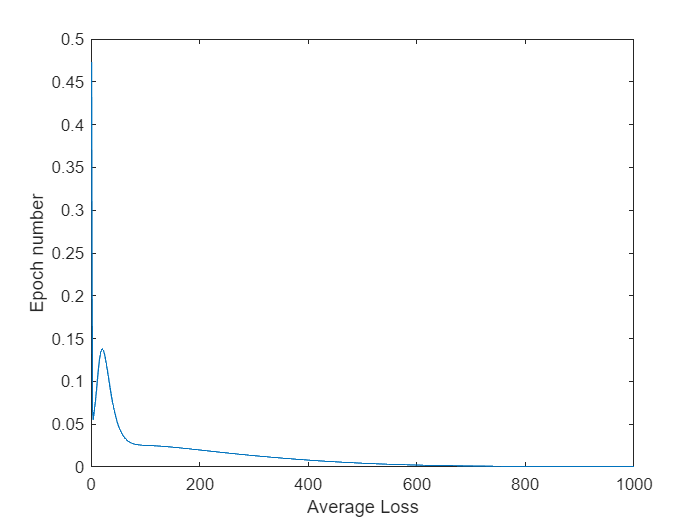

plot(cost_hist);
xlabel('Average Loss')
ylabel('Epoch number')

As we can see from the loss history, we achieve a comparably lower final loss value than in the case of using 2 hidden neurons as our network is better capable of fitting itself to the training data.

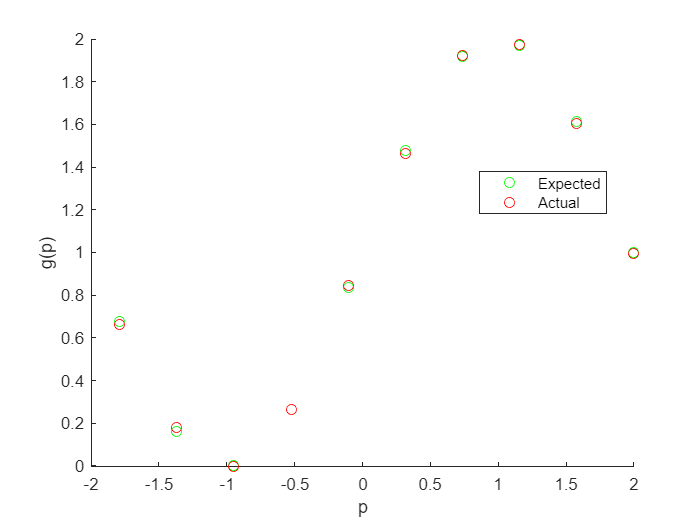

Y_pred = purelin(W2*logsig(W1*X_test + b1) + b2);
scatter(X_test, Y_test, 'green');
hold on;
scatter(X_test, Y_pred, 'red');
xlabel('p');
ylabel('g(p)');
legend('Expected', 'Actual', 'Location','best');
hold off;

From this plot we can also see that the network is capable of producing a much better fit to $g\left(p\right)$ than the case with only 2 hidden neurons.

% Experiment 4: Hidden = 10, Eta = 1
[W1, W2, b1, b2, cost_hist] = MLP(X,Y,10,1);

Loss at the end of epoch 100: NaN
Loss at the end of epoch 200: NaN
Loss at the end of epoch 300: NaN
Loss at the end of epoch 400: NaN
Loss at the end of epoch 500: NaN
Loss at the end of epoch 600: NaN
Loss at the end of epoch 700: NaN
Loss at the end of epoch 800: NaN
Loss at the end of epoch 900: NaN
Loss at the end of epoch 1000: NaN


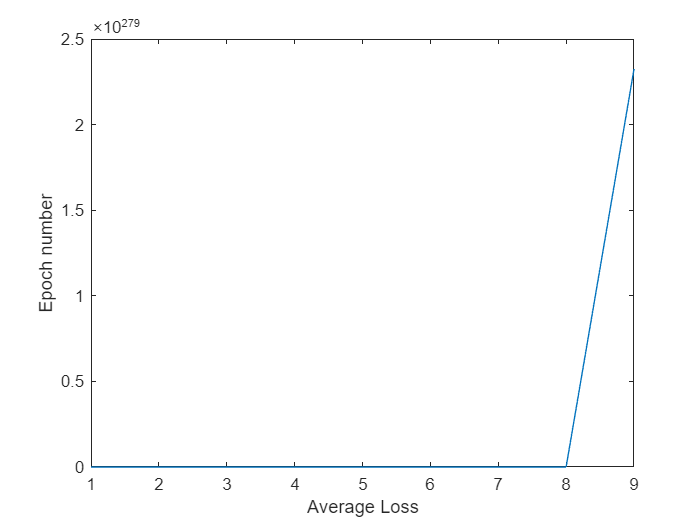

plot(cost_hist);
xlabel('Average Loss')
ylabel('Epoch number')

Again, with a poor choice of learning rate, after only several epochs the average loss goes to infinity.

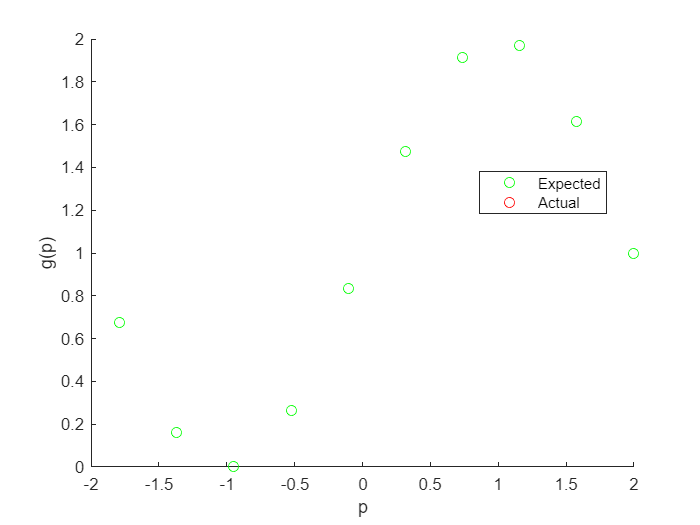

Y_pred = purelin(W2*logsig(W1*X_test + b1) + b2);
scatter(X_test, Y_test, 'green');
hold on;
scatter(X_test, Y_pred, 'red');
xlabel('p');
ylabel('g(p)');
legend('Expected', 'Actual', 'Location','best');
hold off;

Here, the weights and biases grew unboundedly to the extent tht we cannot even produce predictions because of $\textrm{NaN}$ values.

% Experiment 5: Hidden = 100, Eta = 0.02
[W1, W2, b1, b2, cost_hist] = MLP(X,Y,100,0.02);

Loss at the end of epoch 100: 0.004539
Loss at the end of epoch 200: 0.006288
Loss at the end of epoch 300: 0.005086
Loss at the end of epoch 400: 0.003060
Loss at the end of epoch 500: 0.001547
Loss at the end of epoch 600: 0.000720
Loss at the end of epoch 700: 0.000366
Loss at the end of epoch 800: 0.000256
Loss at the end of epoch 900: 0.000245
Loss at the end of epoch 1000: 0.000258


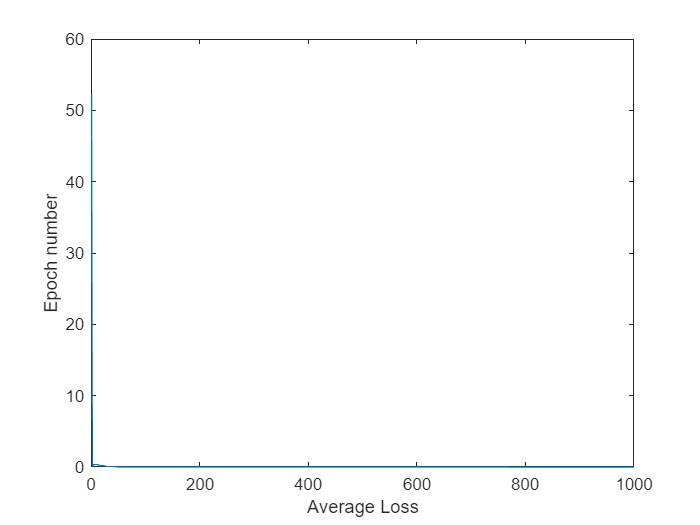

plot(cost_hist);
xlabel('Average Loss')
ylabel('Epoch number')

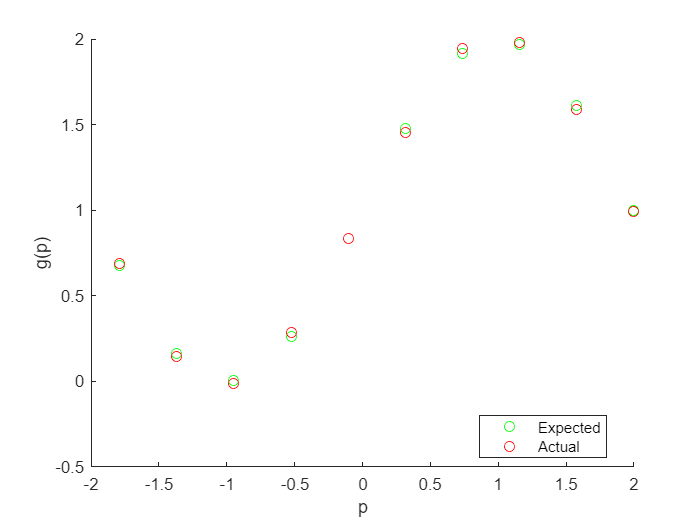

Y_pred = purelin(W2*logsig(W1*X_test + b1) + b2);
scatter(X_test, Y_test, 'green');
hold on;
scatter(X_test, Y_pred, 'red');
xlabel('p');
ylabel('g(p)');
legend('Expected', 'Actual', 'Location','best');
hold off;

As we can see the network produces a slightly poorer fit to the test data although it's training loss is less than the case with $S^1 =10$.